# Sample 3-2

## 平滑化／先鋭化処理

移動平均とラプラシアン 

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Image smoothing/sharpening

Moving averages and Laplacian

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### サンプル画像の準備

(Preparation of sample image)

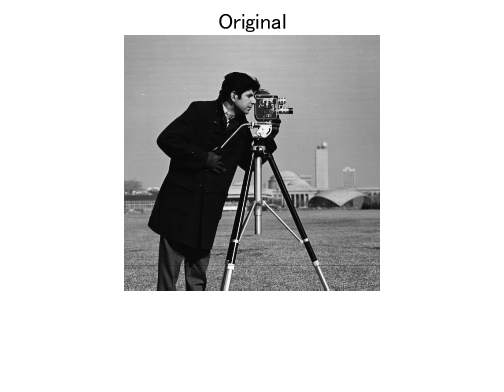

close
% Reading original image
I = im2double(imread('cameraman.tif'));
imshow(I)
title('Original')

### 移動平均フィルタ

(Moving average filter)

以下に$3\times 3$サイズの平均値カーネルを示す。

(The averaging kernel of size $3\times 3$is shown below.)


$$\mathbf{f}=\frac{1}{9}\left(\begin{array}{ccc}
1 & 1 & 1 \\
1 & 1 & 1 \\
1 & 1 & 1
\end{array}\right)$$


% Kernel size setting
hsize = 3;

% Generating the filter kernel
f = fspecial('average',hsize)

f =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


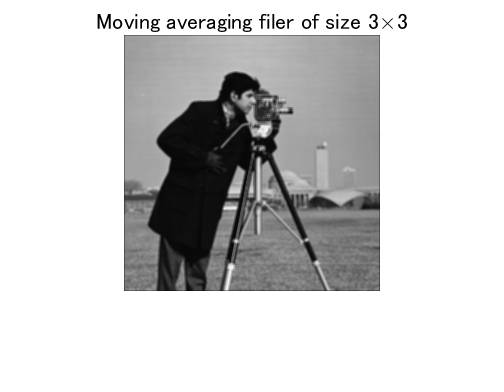

% Moving average filter
J = imfilter(I,f);

% Show the result
imshow(J)
title(['Moving averaging filer of size ' num2str(hsize) '\times' num2str(hsize)])

### ガウシアンフィルタ

(Gaussian filter)

$3\times 3$ サイズのガウシアンフィルタの定義を以下に示す。

(The definition of a Gaussian filter of size $3\times 3$ is given below.)


$$\mathbf{f}=\frac{1}{\sum_{j=-1}^{1}\sum_{i=-1}^{1}g(i,j)}\left(\begin{array}{ccc}
g(-1,-1) & g(-1,0) & g(-1,1) \\
g(0,-1) & g(0,0) & g(0,1) \\
g(1,-1) & g(1,0) & g(1,1)
\end{array}\right),$$


ただし，$\sigma$ を標準偏差として

(where let $\sigma$ be a standard deviation and )


$$g(p_1,p_2)=\exp\left(-\frac{p_1^2+p_2^2}{2\sigma^2}\right).$$


% Setting of kernel size and standard deviation
hsize = 3;
sigma = 0.5;

% Generating the filter kernel
f = fspecial('gaussian',hsize,sigma)

f =     0.0113    0.0838    0.0113
    0.0838    0.6193    0.0838
    0.0113    0.0838    0.0113


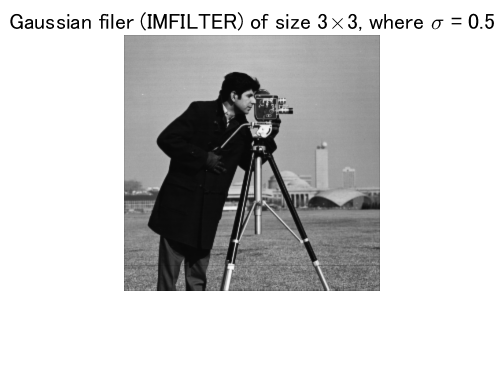

% Gaussian filtering with IMFILTER
J = imfilter(I,f);

% Show result
imshow(J)
title(['Gaussian filer (IMFILTER) of size ' num2str(hsize) '\times' num2str(hsize) ', where \sigma = ' num2str(sigma)])

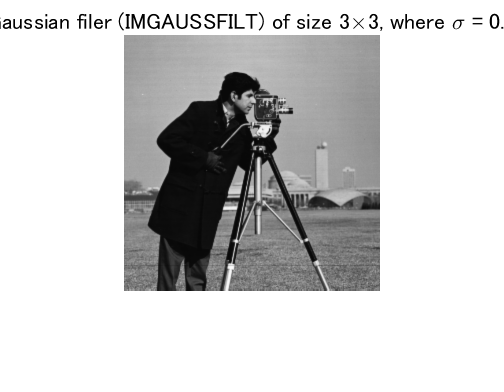

% Gaussian filtering with IMGAUSSFILT
K = imgaussfilt(I,sigma);

% Kernel size
hsize = 2*ceil(2*sigma)+1;

% Show the result
imshow(K)
title(['Gaussian filer (IMGAUSSFILT) of size ' num2str(hsize) '\times' num2str(hsize) ', where \sigma = ' num2str(sigma)])

### ラプラシアンフィルタ

(Laplacian filter)

以下に4近傍ラプラシアンカーネルを示す。

(The four neighborhood Laplacian kernel is  shown below.)


$$\mathbf{f}=\left(\begin{array}{ccc}
0 & 1 & 0 \\
1 & -4 & 1 \\
0 & 1 & 0
\end{array}\right)$$


% Shape parameter setting
alpha = 0;

% Generating the filter kernel
f = fspecial('laplacian',alpha)

f =      0     1     0
     1    -4     1
     0     1     0


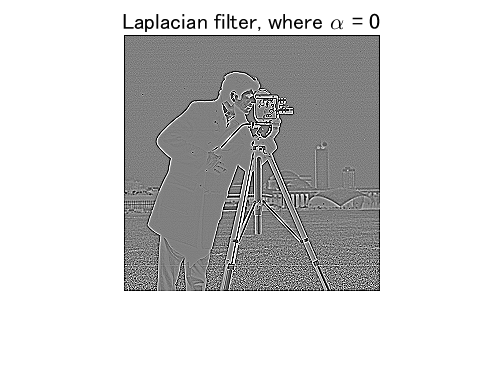

% Laplacian filtering
J = imfilter(I,f);

% Show the result with bias
imshow(J+.5)
title(['Laplacian filter, where \alpha = ' num2str(alpha)])

### アンシャープマスクフィルタ

(Unsharp mask filter)

以下に4近傍ラプラシアンカーネルを示す。

(The four neighborhood Laplacian kernel is  shown below.)


$$\mathbf{f}=\left(\begin{array}{ccc}
0 & -1 & 0 \\
-1 & 5 & -1 \\
0 & -1 & 0
\end{array}\right)$$


% Shape parameter setting
alpha = 0;

% Generating the filter kernel
f = fspecial('unsharp',alpha)

f =      0    -1     0
    -1     5    -1
     0    -1     0


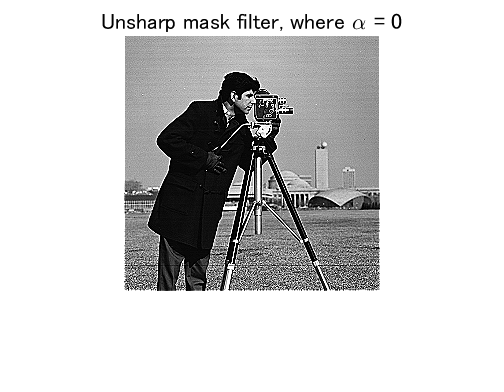

% Unsharp mask filtering
J = imfilter(I,f);

% Show result
imshow(J)
title(['Unsharp mask filter, where \alpha = ' num2str(alpha)])

### ソーベルフィルタ

(Sobel filter)

ソーベル水平フィルタカーネル

(Sobel horizontal filter kernel)


$$\mathbf{f}=\left(\begin{array}{ccc}
-1 & 0 & 1 \\
-2 & 0 & 2 \\
-1 & 0 & 1
\end{array}\right)$$


% Generating the filter kernel
f = fspecial('sobel');
f = rot90(f,-1)

f =     -1     0     1
    -2     0     2
    -1     0     1


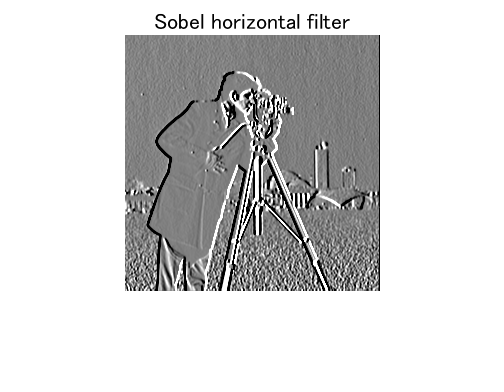

% Sobel horizontal filtering
H = imfilter(I,f);

% Show result with bias
imshow(H+.5)
title('Sobel horizontal filter')

ソーベル水平フィルタカーネル

(Sobel vertical filter kernel)


$$\mathbf{f}=\left(\begin{array}{ccc}

-1 & -2 & -1 \\
0 & 0 & 0 \\
1 & 2 & 1
\end{array}\right)$$


% Generating the filter kernel
f = fspecial('sobel');
f = flipud(f)

f =     -1    -2    -1
     0     0     0
     1     2     1


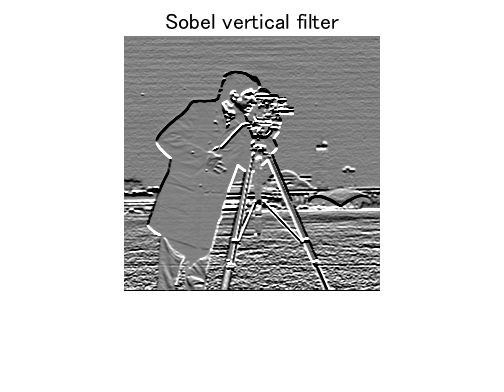

% Sobel vertical filtering
V = imfilter(I,f);

% Show result with bias
imshow(V+.5)
title('Sobel vertical filter')

© Copyright, Shogo MURAMATSU, All rights reserved.